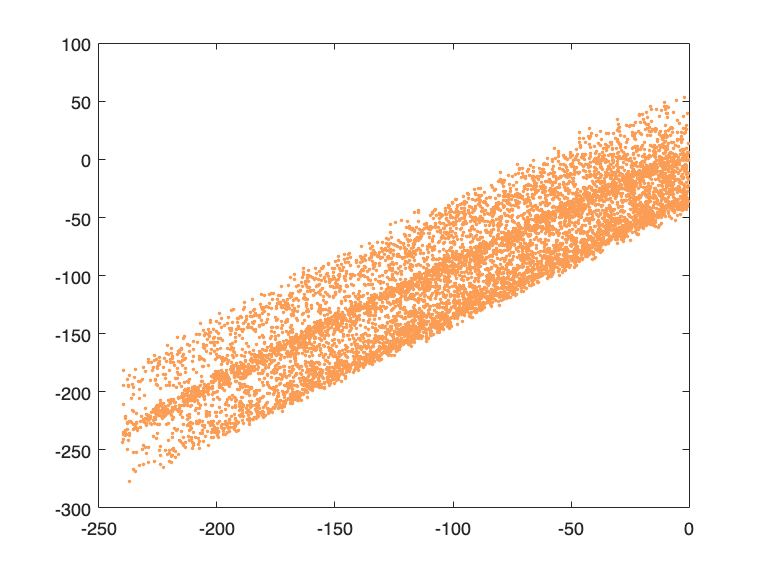

filename = 'DatasetElectricMotor.csv'; 
data = csvread(filename,1,0);

%finding correlations between inputs and outputs
covar = cov(data);
cor = corrcov(covar);

%plotting correlations 
C = linspecer(12);
plot(data(:, 1), data(:, 6), '.',  'Color',C(9, :))

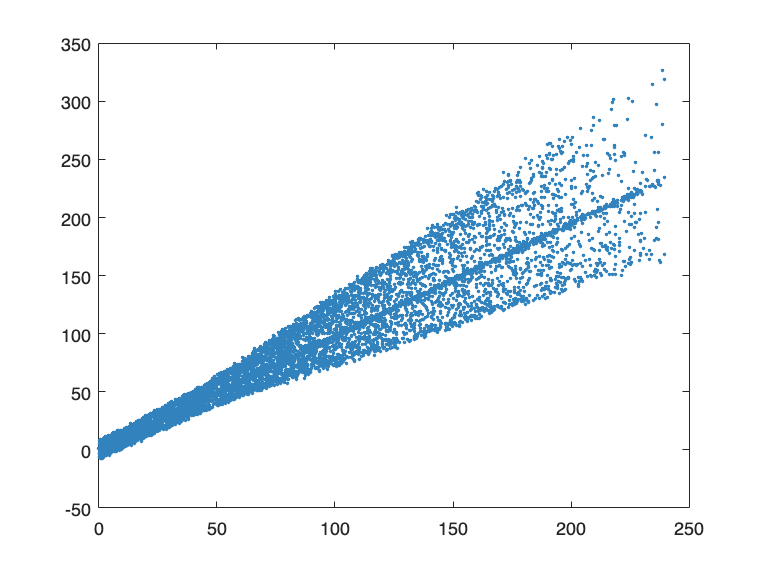

plot(data(:, 2), data(:, 7), '.', 'Color',C(2, :))

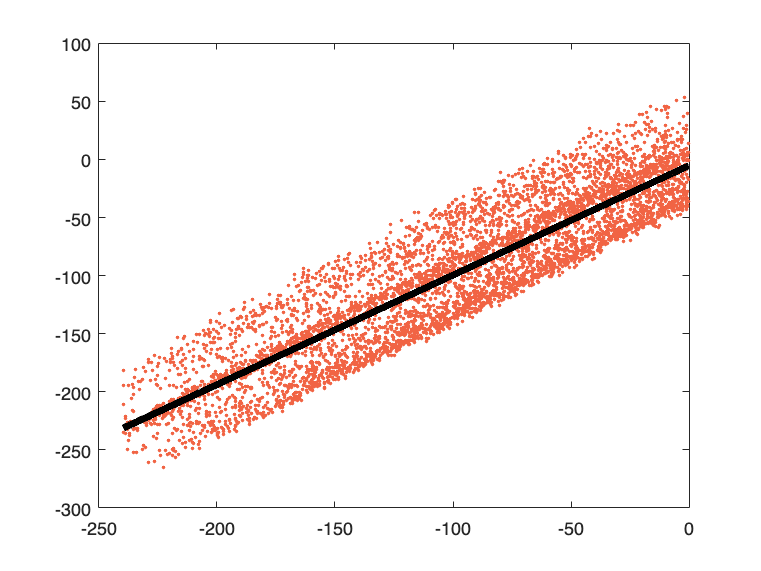

x1 =     0.9427
   -5.3076


r1 = 81.3834

A1 =   -81.4580    1.0000
 -140.6821    1.0000
 -127.0724    1.0000
  -42.2788    1.0000
  -48.0200    1.0000
 -101.8831    1.0000
 -174.9975    1.0000
 -126.3101    1.0000
 -132.9475    1.0000
  -19.2733    1.0000



%splitting data into testing and training blocks 
[trainInd,testInd] = divideblock(size(data,1),0.8,0.2);
x_train = data(trainInd, 1:5); y_train = data(trainInd,  6:7);
x_test = data(testInd, 1:5); y_test = data(testInd, 6:7);

%getting parameters, R coefficients and A matrix for the two corrolations
[x1, r1, A1] = getparams([x_train(:, 1)'; y_train(:, 1)'], 1)

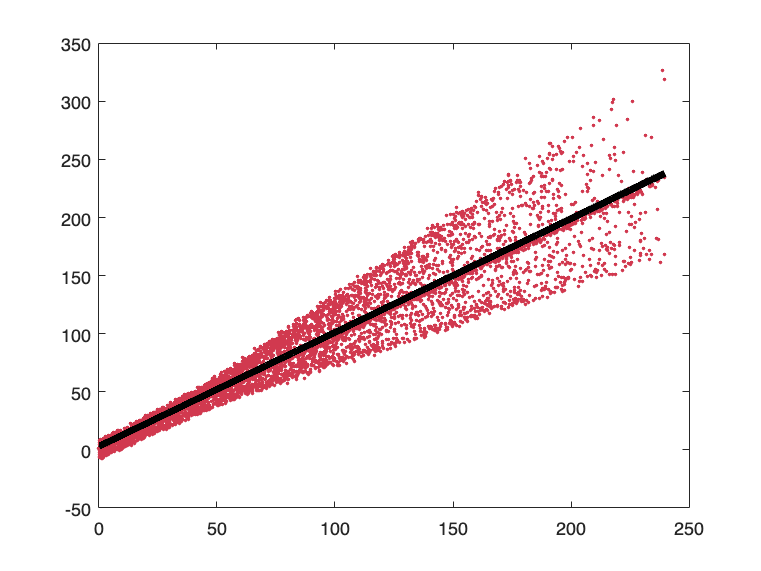

x2 =     0.9801
    3.0356


r2 = 89.3556

A2 =   229.5293    1.0000
  112.4234    1.0000
  171.7438    1.0000
  120.1495    1.0000
   10.9713    1.0000
  171.4520    1.0000
   16.0684    1.0000
   20.0438    1.0000
    8.3752    1.0000
   29.3746    1.0000


[x2, r2, A2] = getparams([x_train(:, 2)'; y_train(:, 2)'], 1)

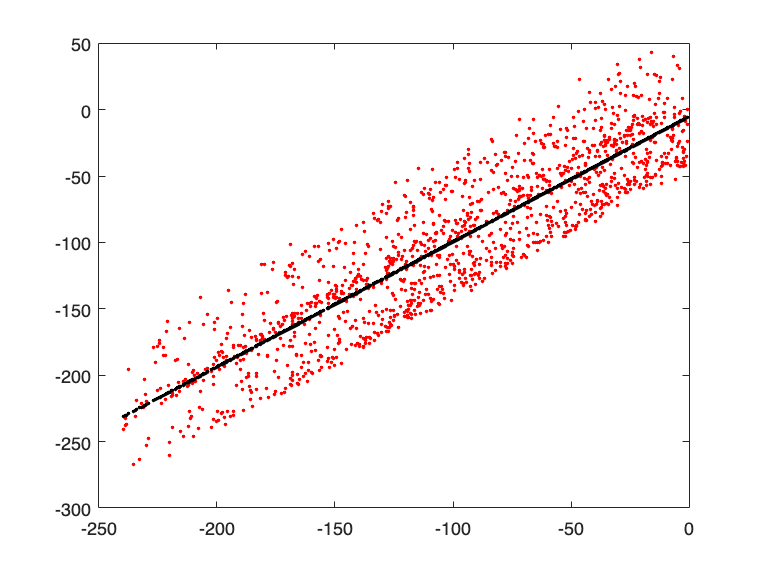


%making y fit using parameters and A matrix 
y1_fit_trained = A1*x1;
y1_fit_testing = [x_test(:, 1) x_test(:, 1).^0]*x1;
%y1_fit_testing = [x_test(:, 1).^2 x_test(:, 1) x_test(:, 1).^0]*x1;
y2_fit_trained = A2*x2;
y2_fit_testing = [x_test(:, 2) x_test(:, 2).^0]*x2;
%y2_fit_testing = [x_test(:, 2).^2 x_test(:, 2)  x_test(:, 2).^0]*x2;

%comparing to test matrices
plot(x_test(:,1), y_test(:,1), '.r', x_test(:, 1), y1_fit_testing, '.k')

R1 = 100*(1-sum((y_test(:,1)-y1_fit_testing(:)).^2)/sum((y_test(:, 1)-mean(y_test(:, 1))).^2))

R1 = 81.1566

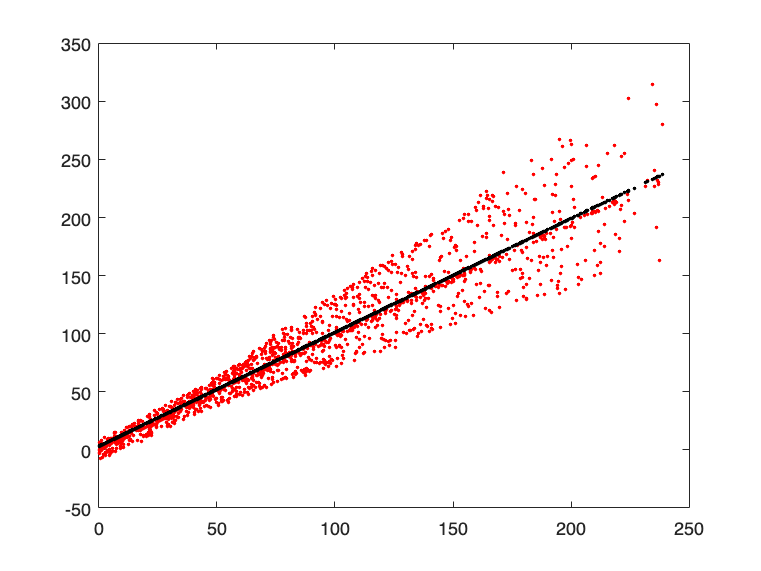

plot(x_test(:,2), y_test(:,2), '.r', x_test(:, 2), y2_fit_testing, '.k')

R2 = 100*(1-sum((y_test(:,2)-y2_fit_testing(:)).^2)/sum((y_test(:, 2)-mean(y_test(:, 2))).^2))

R2 = 90.1017


%calculating MSE 
mse_train1 = immse([x_train(:,1) y_train(:,1)],[x_train(:,1) y1_fit_trained] )

mse_train1 = 391.7399

mse_test1 = immse([x_test(:,1) y_test(:,1)],[x_test(:, 1) y1_fit_testing] )

mse_test1 = 387.1322

mse_train2 = immse([x_train(:,2) y_train(:,2)],[x_train(:,2) y2_fit_trained] )

mse_train2 = 202.0431

mse_test2 = immse([x_test(:,2) y_test(:,2)],[x_test(:, 2) y2_fit_testing] )

mse_test2 = 189.4897